# 最小拍控制系统

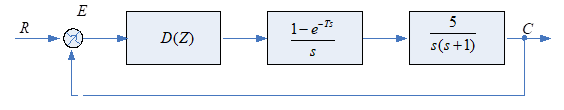

`采样周期为`**T=0.1s**

T=0.1;
G=zpk([],[0 -1],5);
display(G)

G =
 
     5
  -------
  s (s+1)
 
Continuous-time zero/pole/gain model.



## `最小拍有纹波系统`

`针对图一所示的计算机控制系统,考虑输入为单位速度信号时，进行``计算机控制算法``D(Z)``设计，编程实现最小拍有纹波系统；`

`（1）该系统的广义脉冲传递函数为：`

Wd=c2d(G,T,'zoh');
%Wd的零极点
[zero,pole,~]=zpkdata(Wd);
zero=zero{1};pole=pole{1};
display(Wd);

Wd =
 
  0.024187 (z+0.9672)
  -------------------
   (z-1) (z-0.9048)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



从结果可以看出，广义脉冲传递函数没有不稳定的零极点，没有纯滞后环节，系统稳定，可以使用对简单对象的最小拍控制的设计方法

由于输入为单位速度信号$r(t)=t$,查表5.1[2]得

z=tf('z',T);
We=(1-z^-1)^2

We =
 
  z^2 - 2 z + 1
  -------------
       z^2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



WB=2*z^(-1)-z^(-2);
WB=minreal(WB)

WB =
 
  2 z - 1
  -------
    z^2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



（2）数字控制器的脉冲传递函数为

D=WB/(Wd*(1-WB))

D =
 
  82.689 z^2 (z-0.5) (z-0.9048) (z-1)
  -----------------------------------
        z^2 (z+0.9672) (z-1)^2
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



WB=minreal(D*Wd/(1+D*Wd))

WB =
 
           2 (z-0.5)
  ---------------------------
  (z+1.722e-08) (z-1.722e-08)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



（3）分析数字控制器D(z)对系统的控制效果

%计算采样点前的传递函数
% Phi=feedback(series(D,G),1);

当控制型号为单位速度信号时

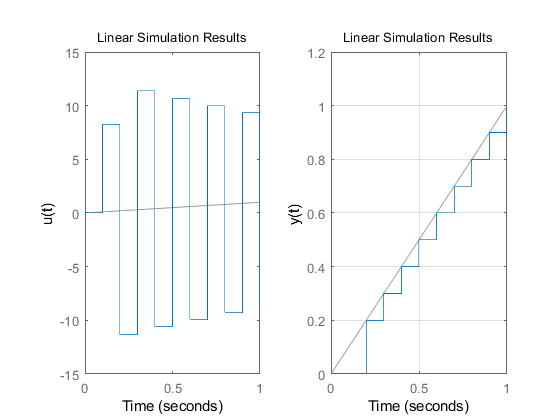

figure();
subplot(1,2,1)
lsimplot(WB/Wd,0:0.1:1,0:0.1:1);
ylabel('u(t)');
subplot(1,2,2);
lsimplot(WB,0:0.1:1,0:0.1:1);
grid on;
ylabel('y(t)');

当控制信号为单位阶跃信号时：

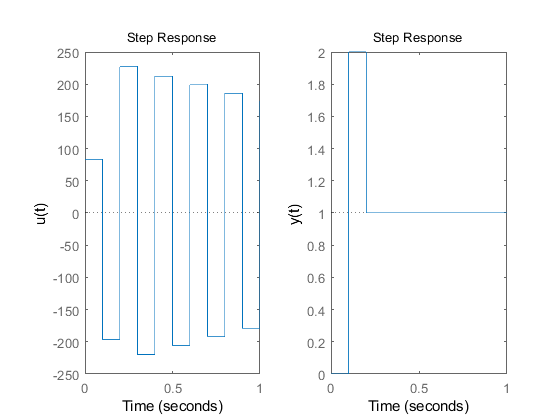

figure()
subplot(1,2,1)
stepplot(WB/Wd,1);
ylabel('u(t)');
subplot(1,2,2)
stepplot(WB,1);
ylabel('y(t)');

当控制信号为单位脉冲信号时

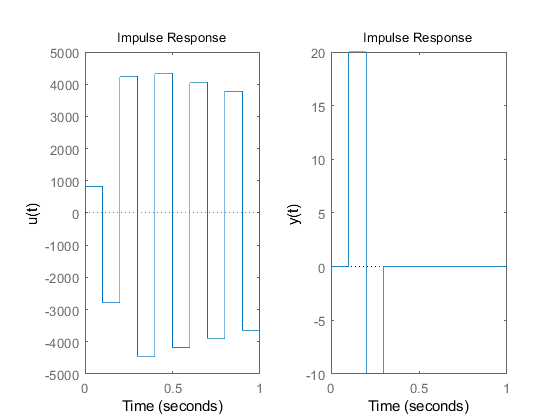

figure()
subplot(1,2,1)
impulseplot(WB/Wd,1);
ylabel('u(t)');
subplot(1,2,2);
impulseplot(WB,1);
ylabel('y(t)');

## `最小拍无纹波系统`

讨论纹波的生成原因，编程实现最小拍无纹波系统；

如果系统进入稳态后，加在被控对象上的控制信号还在波动，则稳态过程中系统输出就有纹波

（1）求对象广义脉冲传递函数$$W_d$$

（2）确定闭环系统脉冲传递函数$W_B(z)
$

最小拍无纹波控制必须满足以下条件

- 被控对象W(s)中必须包含足够多的积分环节(>=m-1阶)，输入单位阶跃信号时为m=1

- 满足纹波控制的稳定性和控制器的物理可实现

- $W_B(z)$包含W(z)中的所有零点

所以可以通过


$$W_B(z)=f_1z^{-1}(1+\beta_1 z^{-1})$$


f1=1/(1+zero(1));
WB2=f1*z^(-1)*(1+zero(1)*z^(-1))

WB2 =
 
  30.5 z - 29.5
  -------------
       z^2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



（3）数字控制器D的计算

该系统物理可实现

D2=1/Wd*WB2/(1-WB2)

D2 =
 
  1261.2 z^2 (z-1) (z-0.9672) (z-0.9048)
  --------------------------------------
      z^2 (z+0.9672) (z-1) (z-29.5)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



（4）控制信号和输出响应计算

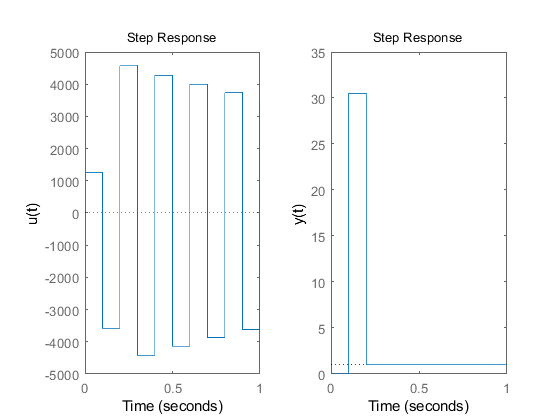

figure()
subplot(1,2,1)
stepplot(WB2/Wd,1);
ylabel('u(t)');
subplot(1,2,2)
stepplot(WB2,1);
ylabel('y(t)');

## `改进最小拍系统`

`讨论最小拍系统的特点，采取惯性因子法对最小拍控制器加以改进，并研究惯性因子对系统性能的影响。`

c=0.45;

`脉冲闭环传递函数可以设计为：`


$$W_B(z)=\frac{f_1z^{-1}+f_2z^{-2}}{1-cz^{-1}}$$


其中f1和f2通过以下条件得出

$W_B(z)|_{z=1}=1 \ and \ 
\frac{\mathrm{d}W_B(z)}{\mathrm{d}z}|_{z=1}=0
\Rightarrow
f_1=2-c\  and \ f_2=-1$\

f1=2-c;f2=-1;
WB3=tf([f1 f2],[1 -c 0],T)

WB3 =
 
   1.55 z - 1
  ------------
  z^2 - 0.45 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



该系统物理可实现

We3=1-WB3;
D3=1/Wd*WB3/We3;
display(D3)

D3 =
 
  64.084 z (z-1) (z-0.9048) (z-0.6452) (z-0.45)
  ---------------------------------------------
          z (z+0.9672) (z-1)^2 (z-0.45)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



当控制型号为单位速度信号时

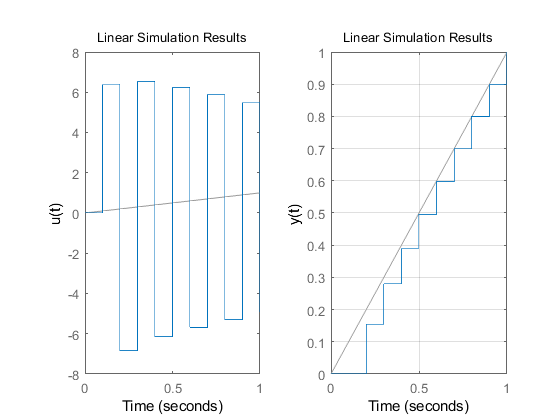

figure();
subplot(1,2,1)
lsimplot(WB3/Wd,0:0.1:1,0:0.1:1);
ylabel('u(t)');
subplot(1,2,2);
lsimplot(WB3,0:0.1:1,0:0.1:1);
grid on;
ylabel('y(t)');

当控制信号为单位阶跃信号时：

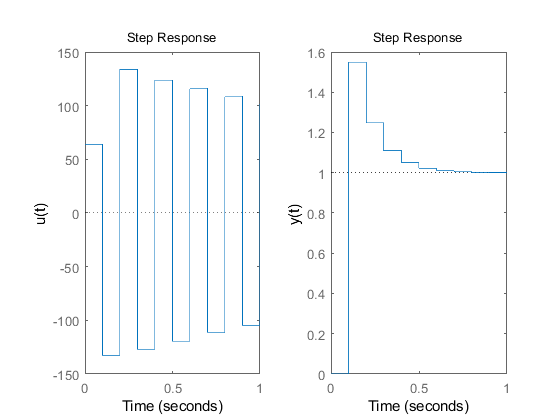

figure()
subplot(1,2,1)
stepplot(WB3/Wd,1);
ylabel('u(t)');
subplot(1,2,2)
stepplot(WB3,1);
ylabel('y(t)');

当控制信号为单位脉冲信号时

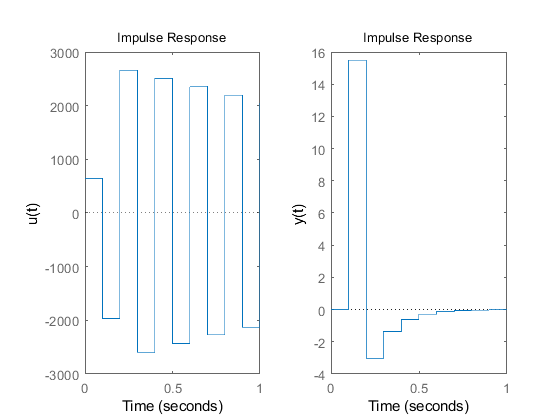

figure()
subplot(1,2,1)
impulseplot(WB3/Wd,1);
ylabel('u(t)');
subplot(1,2,2);
impulseplot(WB3,1);
ylabel('y(t)');

### 分析`惯性因子对系统性能的影响`

`绘制不同c取值下的输出阶跃响应图和系统主要性能参数表`

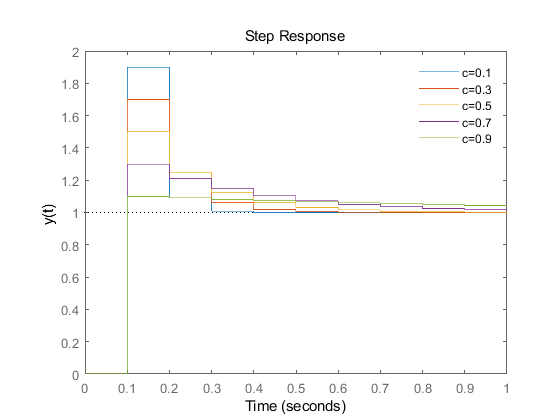

figure();hold on;
C=0.1:0.2:0.9;
N=length(C);
%预分配内存
info=repmat(stepinfo(tf(1,1)),[N 1]);
for i=1:N
    c=C(i);
    f1=2-c;f2=-1;
    WB3=tf([f1 f2],[1 -c 0],T);
    We3=1-WB3;
    D3=1/Wd*WB3/We3;
    stepplot(WB3,1);
    info(i)=stepinfo(WB3);
    ylabel('y(t)');
end
n4 = length(C);
tmp4 = cell(n4,1);
for i4 = 1:n4
    tmp4{i4} = sprintf('c=%g',C(i4));
end
legend(tmp4);
hold off;

info=struct2table(orderfields(info,[5,2,1,3,4,7,8,6]),'RowNames',tmp4);
display(info);

info = 5×8 table
             Overshoot    SettlingTime    RiseTime    SettlingMin    SettlingMax    Peak    PeakTime    Undershoot
             _________    ____________    ________    ___________    ___________    ____    ________    __________

    c=0.1       90            0.3            0             1             1.9        1.9       0.1           0     
    c=0.3       70            0.4            0             1             1.7        1.7       0.1           0     
    c=0.5       50            0.6            0             1             1.5        1.5       0.1           0     
    c=0.7       30            0.9            0             1             1.3        1.3       0.1           0     
    c=0.9       10            1.7            0             1             1.1        1.1       0.1           0     


观察以上结果可知，c越大准确性越好。

## `参考文献`

- [https://link.springer.com/chapter/10.1007%2F978-3-642-21697-8_21](https://link.springer.com/chapter/10.1007%2F978-3-642-21697-8_21)

- `刘建昌.计算机控制系统（第二版）.2016,137`